# Sample 13-3

## 辞書学習

K-特異値分解

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Dictionary learning

K-SVD

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### パラメータ設定

(Parameter settings)

- ブロックサイズ (Block size)

- 冗長率 (Redundancy ratio)

- スパース率 (Sparsity ratio)

- 繰返し回数 (Number of iterations)

% Block size
szBlk = [8 8];
nDims = prod(szBlk);

% Redundancy ratio
redundancyRatio = 1.5;

% Sparsity ratio
sparsityRatio = 0.1;

% Number of iterations
nIters = 30;

## 画像の読込

(Read image)

- 
$$\mathbf{u}\in\mathbb{R}^{N}$$


% Read image
u = rgb2gray(im2double(imread('./data/lena.png')));

### K-特異値分解

 (K-Singular Value Decomposition)

#### 問題設定 (Problem setting):

    
$$\{\hat{\mathbf{\Phi}},\{ \hat{\mathbf{x}} \}\}=\arg\min_{\{\mathbf{\Phi},\{\mathbf{x}\}\}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{y}_n-\mathbf{\Phi}\hat{\mathbf{x}}_n\|_2^2,\ \quad\mathrm{s.t.}\ \forall n, \|\mathbf{x}_n\|\leq K$$$


#### アルゴリズム (Algorithm):

スパース近似ステップと辞書更新ステップを繰返す．

- スパース近似ステップ (Sparse approximation step)

                
$$\hat{\mathbf{x}}_n=\frac{1}{2}\arg\min_{\mathbf{x}_n} \|\mathbf{y}_n-\hat{\mathbf{\Phi}}\mathbf{x}_n\|_2^2\ \quad \mathrm{s.t.}\ \|\mathbf{x}_n\|_0\leq K$$


- 辞書更新ステップ (Dictionary update step)

                
$$\hat{\mathbf{\Phi}}=\arg\min_{\mathbf{\Phi}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{y}_n-\mathbf{\Phi}\hat{\mathbf{x}}_n\|_2^2=\arg\min_{\mathbf{\Phi}}\frac{1}{2S}\left\|\left(\mathbf{Y}-\sum_{p\neq k}\mathbf{\phi}_p\hat{\mathbf{X}}_{p,\colon}\right)-\mathbf{\phi}_k\hat{\mathbf{X}}_{k,\colon}\right\|_F^2$$


画像 $\mathbf{u}$からのデータ行列 $\mathbf{Y}$ の生成 (Generation of data matrix  $\mathbf{Y}$  of image $\mathbf{u}$)

Y = im2col(u,szBlk,'distinct');
nSamples = size(Y,2);

要素画像の数 (Number of atomic images)

nAtoms = ceil(redundancyRatio*nDims);

係数の数 (Number of coefficients)

nCoefs = floor(sparsityRatio*nDims);

辞書 $\mathbf{\Phi}$の初期化 (Initializatio of dictionary $\mathbf{\Phi}$)

- 二変量離散コサイン変換(Bivariate DCT)

- ランダム (random)

Phi = randn(nDims,nAtoms);
Phi = Phi/norm(Phi,'fro');
for iAtom = 1:nDims
    delta = zeros(szBlk);
    delta(iAtom) = 1;
    Phi(:,iAtom) = reshape(idct2(delta),nDims,1);
end

要素ベクトルを要素画像に変換 (Reshape the atoms into atomic images)

atomicImages = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImages(:,:,iAtom) = reshape(Phi(:,iAtom),szBlk(1),szBlk(2));
end

### 画像表示

(Image show)

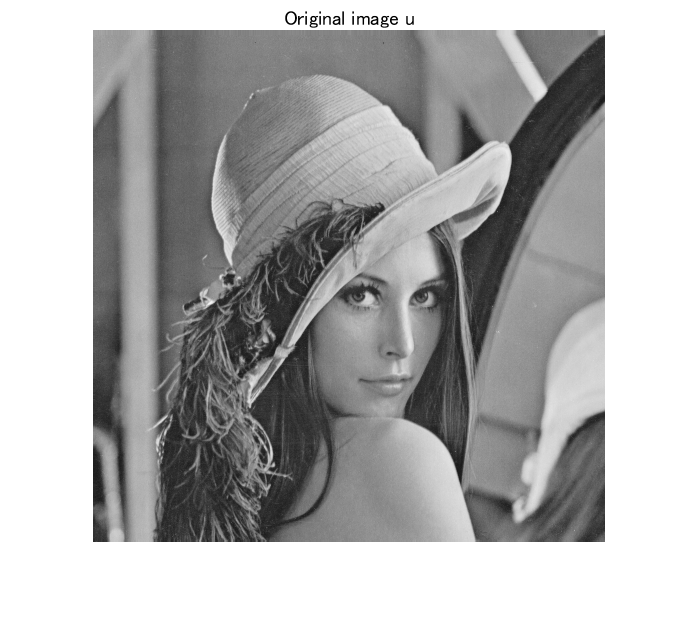

figure(1)
imshow(u);
title('Original image u')

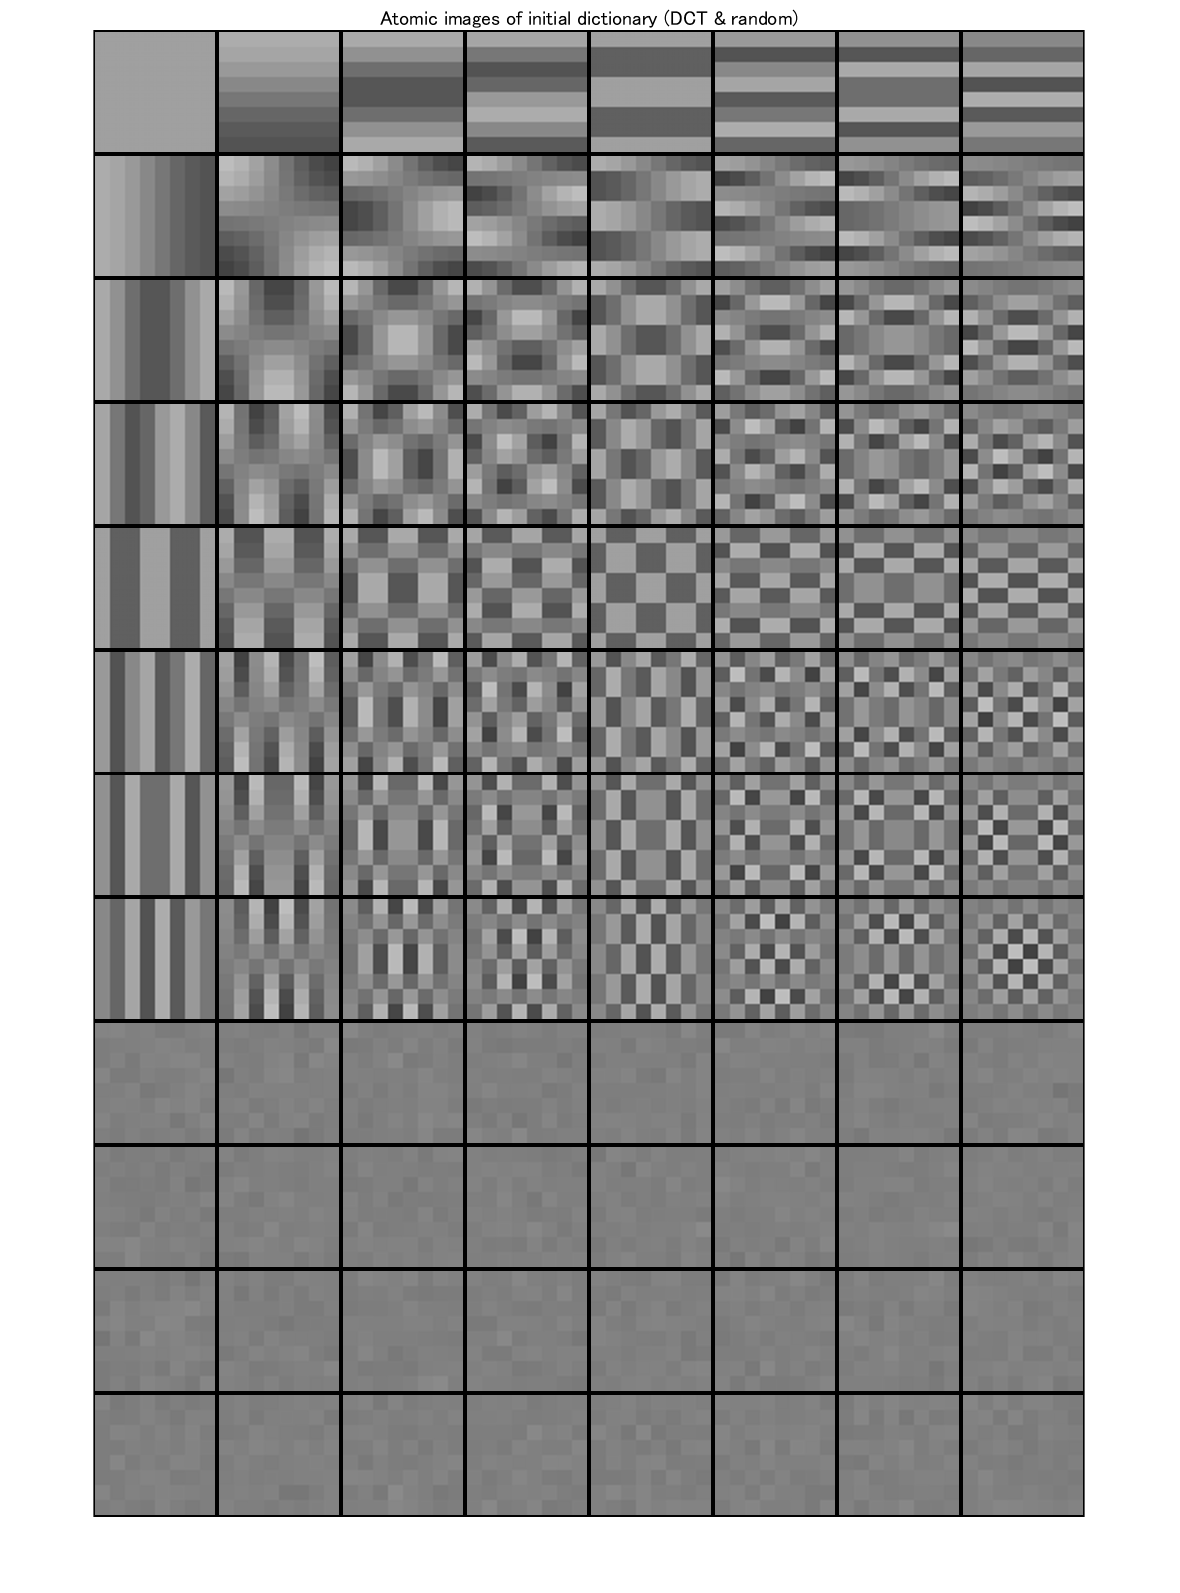

figure(2)
montage(imresize(atomicImages,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of initial dictionary (DCT & random)')

#### スパース近似ステップと辞書更新ステップの繰り返し

- スパース近似： 直交マッチング追跡 (OMP)

- 辞書更新： 特異値分解と1-ランク近似 (SVD and 1-rank approximation)

辞書更新の内容

- 
$$k\leftarrow 1$$


- 誤差行列 $\mathbf{E}_k$ を定義：$\mathbf{E}_k\colon = \mathbf{Y}-\sum_{p\neq k}\mathbf{\phi}_p\hat{\mathbf{X}}_{p,\colon}$

- データ行 $\hat{\mathbf{X}}_{k,\colon}$の非零値を抽出する行列 $\mathbf{\Omega}_k$を定義： $\hat{\mathbf{X}}_{k,\colon}^R=\hat{\mathbf{X}}_{k,\colon}\mathbf{\Omega}_k \Leftrightarrow \hat{\mathbf{X}}_{k,\colon}^R\mathbf{\Omega}_k^T=\hat{\mathbf{X}}_{k,\colon}$

- 誤差行列 $\mathbf{E}_k$ を行列 $\mathbf{\Omega}_k$で縮退： $\mathbf{E}_k^R \colon=\mathbf{E}_k\mathbf{\Omega}_k$

- 縮退した誤差行列$\mathbf{E}_k^R$を特異値分解：$\mathbf{E}_k^R =\mathbf{U}\mathbf{S}\mathbf{V}^T
=\left(\mathbf{u}_1,\mathbf{u}_2,\cdots,\mathbf{u}_r\right)\mathrm{diag}(\sigma_1,\sigma_2,\cdots,\sigma_r)\left(\mathbf{v}_1,\mathbf{v}_2,\cdots,\mathbf{v}_r\right)^T$

- 要素ベクトル $\mathbf{\phi}_k$ を更新： $\mathbf{k}\leftarrow \mathbf{u}_1$

- データ行$\hat{\mathbf{X}}_{k,\colon}$を更新： $\hat{\mathbf{X}}_{k,\colon}\leftarrow \sigma_1\mathbf{v}_{1}^T$

- 
$$k\leftarrow k+1$$


- $k\leq N$ ならば 2. へ $k>N$ ならば終了

ただし， $\sigma_1$ を最大特異値とする．

交互ステップの繰返し計算 (Iterative calculation of alternative steps)

cost = zeros(1,nIters);
for iIter = 1:nIters
    X = zeros(nAtoms,nSamples);
    % Sparse approximation
    for iSample = 1:nSamples
        y = Y(:,iSample);
        x = omp(y,Phi,nCoefs);
        X(:,iSample) = x;
    end
    % Dictionary update
    for iAtom = 1:nAtoms
        idxset = setdiff(1:nAtoms,iAtom);
        xk = X(iAtom,:);
        suppk = find(xk);
        %
        Ekred = Y(:,suppk)-Phi(:,idxset)*X(idxset,suppk);
        %
        if ~isempty(suppk)
            [U,S,V] = svd(Ekred,'econ');
            ak = U(:,1);
            xkred = S(1,1)*V(:,1)';
            %
            Phi(:,iAtom) = ak;
            X(iAtom,suppk) = xkred;
        end
    end
    cost(iIter) = (norm(Y-Phi*X,'fro')^2)/(2*nSamples);
end

コスト評価のグラフ (Graph of cost variation)

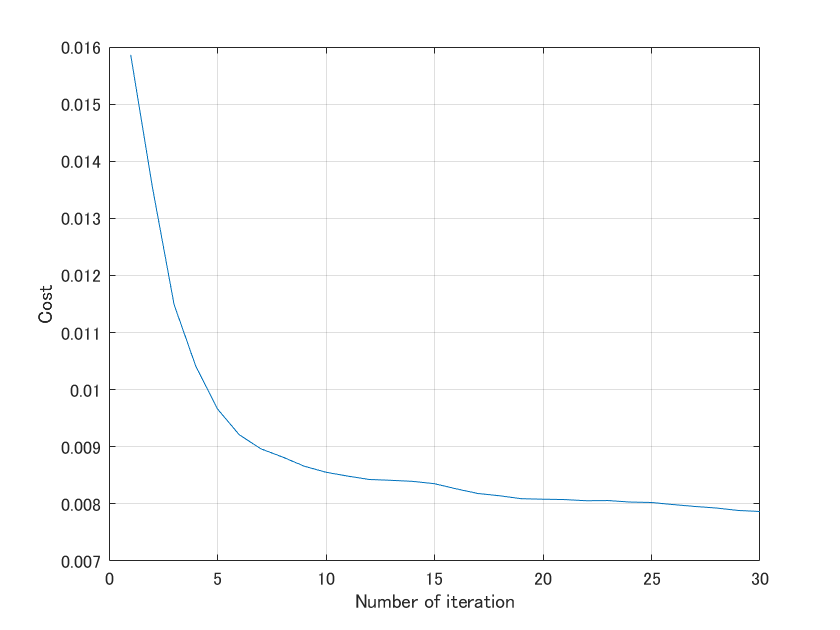

figure(3)
plot(cost)
xlabel('Number of iteration')
ylabel('Cost')
grid on

要素ベクトルを要素画像に変換 (Reshape the atoms into atomic images)

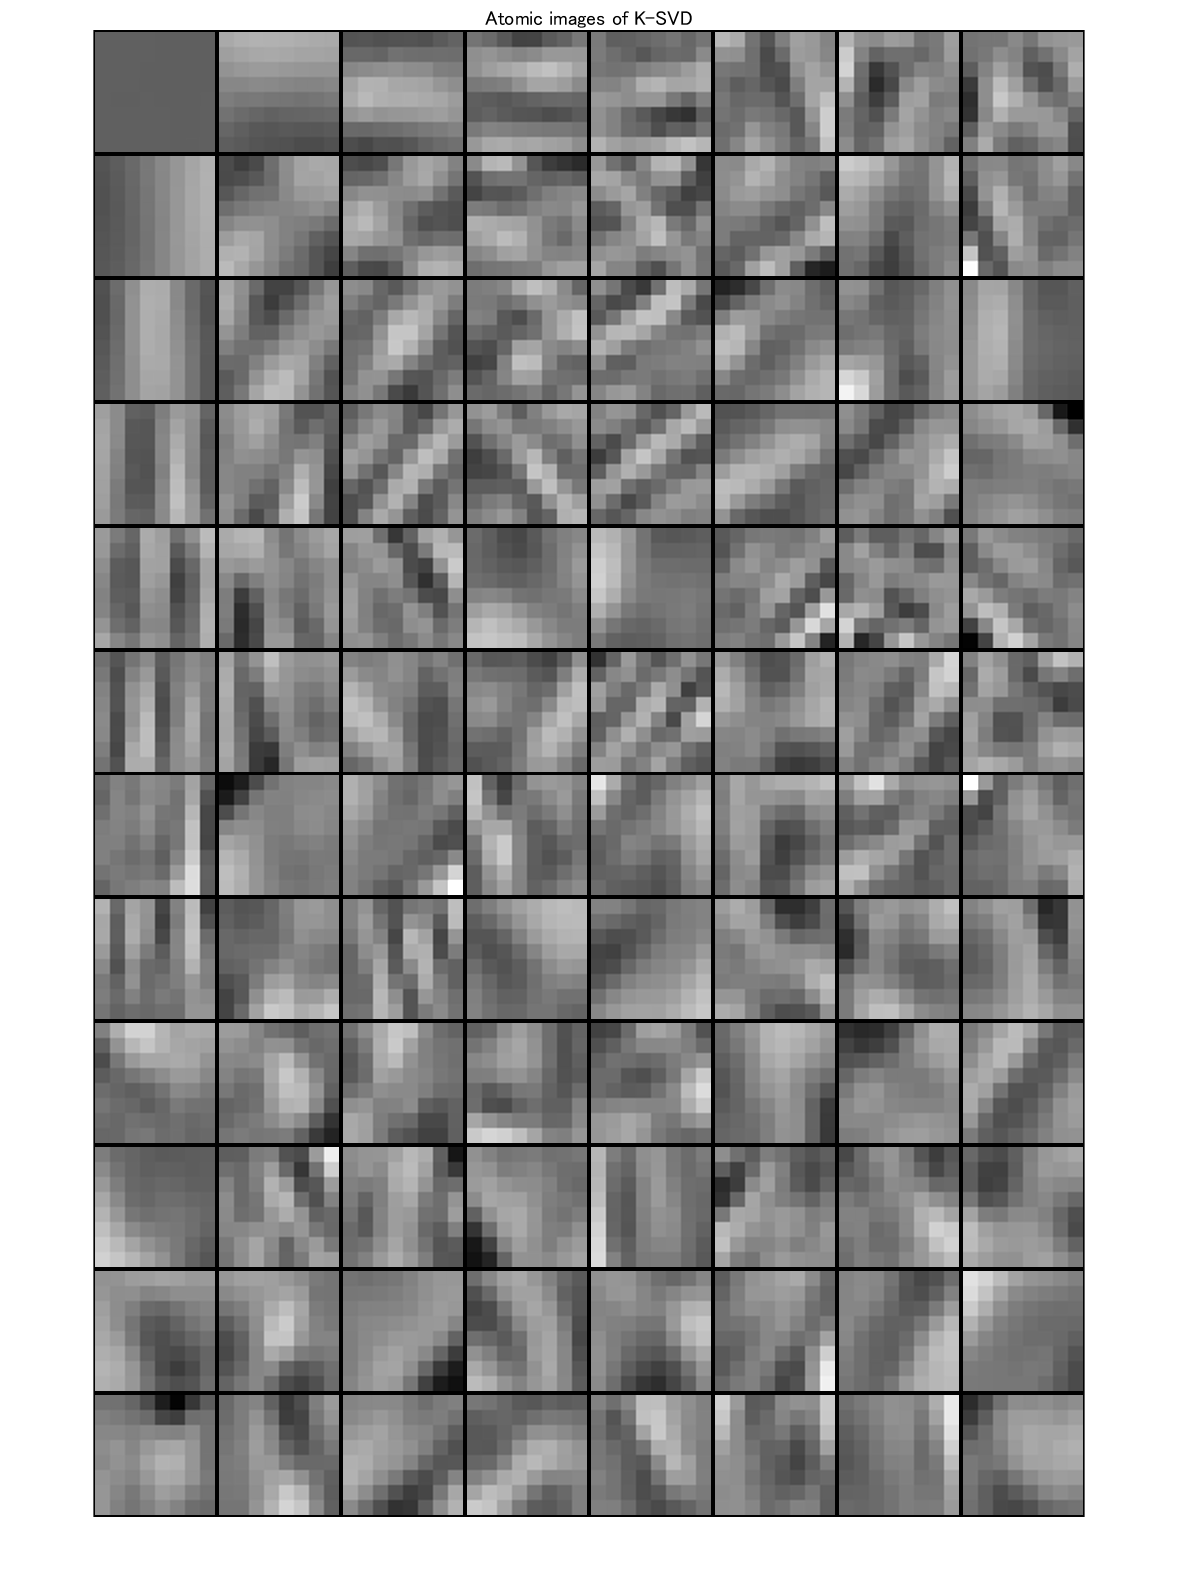

atomicImages = zeros(szBlk(1),szBlk(2),nAtoms);
for iAtom = 1:nAtoms
    atomicImages(:,:,iAtom) = reshape(Phi(:,iAtom),szBlk(1),szBlk(2));
end
figure(4)
montage(imresize(atomicImages,8,'nearest')+.5,'BorderSize',[2 2],'Size',[ceil(nAtoms/8) 8])
title('Atomic images of K-SVD')

### 直交マッチング追跡関数 

(Function of orthogonal matching pursuite)

function x = omp(y,Phi,nCoefs)
    % Initializaton
    nDims = size(Phi,1);
    nAtoms = size(Phi,2);
    e = ones(nAtoms,1);
    a = zeros(nAtoms,1);
    g = zeros(nAtoms,1);
    x = zeros(nAtoms,1);
    v = zeros(nDims,1);
    r = y - v;
    supp = [];
    k = 0;
    while k < nCoefs
        % Matching process
        rr = r.'*r;
        for m = setdiff(1:nAtoms,supp)
            d = Phi(:,m);
            g(m) = d.'*r; % γm=<dm,r>
            a(m) = g(m)/(d.'*d); % Normalize αm=γm/||dm||^2
            e(m) = rr - g(m)*a(m); % <r-dm/||dm||^2,r>
        end
        % Minimum value search (pursuit)
        [~,mmin]= min(e);
        % Update the support
        supp = union(supp,mmin);
        subPhi = Phi(:,supp);
        x(supp) = pinv(subPhi) * y;
        % Synthesis process
        v = Phi*x;
        % Residual
        r = y - v;
        % Update
        k = k + 1;
    end
end

© Copyright, Shogo MURAMATSU, All rights reserved.